Problem 6.11

A normalized second-order system with a damping ratio zeta = 0.5 and an additional zero is given by 

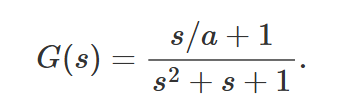

Use Matlab to compare Mp from the step response of the system for a = 0.01, 0.1, 1, 10, and 100 with the Mr from the frequency response of each case. Is there a correlation between Mr and Mp?

## Bode Plots:

a = [0.01, 0.1, 1, 10, 100];

figure;
hold on;

for index = a
    num = [1/index, 1]; 
    den = [1, 1, 1];    
    
    L = tf(num, den);
    
    bode(L);
end

grid on;
hold off;

## Mr vs Mp:

a = [0.01, 0.1, 1, 10, 100];

Mr_values = zeros(size(a));
Mp_values = zeros(size(a));

for i = 1:length(a)
    index = a(i);
    num = [1/index, 1]; 
    den = [1, 1, 1];    
    
    L = tf(num, den);
    
    [peak_gain_linear, ~] = getPeakGain(L);
    Mr_values(i) = 20 * log10(peak_gain_linear);
    
    [y, t] = step(L);
    y_final = y(end);            
    y_peak = max(y);             
    Mp_values(i) = ((y_peak - y_final) / y_final) * 100;
   
end

figure;

yyaxis left
semilogx(a, Mr_values, '-o', 'LineWidth', 2, 'MarkerSize', 6);
grid on;

yyaxis right
semilogx(a, Mp_values, '-s', 'LineWidth', 2, 'MarkerSize', 6);

xlabel('Parameter a');
title('Comparison of M_r and M_p vs. Parameter a');
legend('M_r (dB)', 'M_p (%)', 'Location', 'best');